clf;
clear;

lena = imread("../images/lena_gray_256.tif");
size(lena)

ans =    256   256


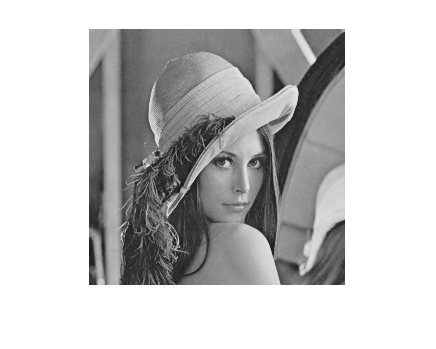

lena = lena(:,:,1);
imshow(lena);

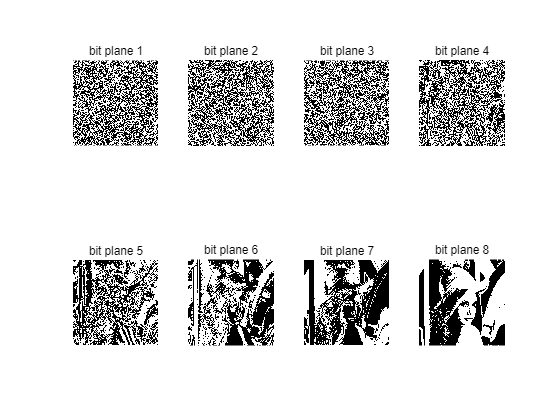

B=BitPlaneSlicing(lena);
% B1=bitget(lena,1);
% B2=bitget(lena,2);
% B3=bitget(lena,3);
% B4=bitget(lena,4);
% B5=bitget(lena,5);
% B6=bitget(lena,6);
% B7=bitget(lena,7);
% B8=bitget(lena,8);

figure;
subplot(2,4,1);
%imshow(logical(B1));title('bit plane 1');
imshow(B(:,:,1));title('bit plane 1');
subplot(2,4,2);
imshow(B(:,:,2));title('bit plane 2');
subplot(2,4,3);
imshow(B(:,:,3));title('bit plane 3');
subplot(2,4,4);
imshow(B(:,:,4));title('bit plane 4');
subplot(2,4,5);
imshow(B(:,:,5));title('bit plane 5');
subplot(2,4,6);
imshow(B(:,:,6));title('bit plane 6');
subplot(2,4,7);
imshow(B(:,:,7));title('bit plane 7');
subplot(2,4,8);
imshow(B(:,:,8));title('bit plane 8');

**Function: Bit Plane Slicing**

function output = BitPlaneSlicing(input)
    input = double(input);
    [row,col] = size(input);
    output = zeros(row,col,8);

    input_bin = dec2bin(input,8);
    input_bin = reshape(input_bin(:),row,col,8);
    for i = 1:row
        for j = 1:col
            for k = 1:8
                if input_bin(i,j,9-k) == '0'
                    output(i,j,k) = 0;
                else
                    output(i,j,k) = 1;
                end
            end 
        end
    end
end